# Survey on controllers

## Simulation parameters

clc
% Simulation time (ms)
T = 1000;
% Simulation step (ms)
dt  = 1;
idt = 1;

qi  = [0; 0]; % Initial joint state
dqi = [0; 0]; % Initial joint velocity
ddqi= [0; 0]; % Initial joint acceleration
ui  = [0; 0]; % Initial torque input
% Final conditions
qd  = [pi/2; -pi/2]; % Final joint state
dqd = [0; 0]; % Final joint velo city
ddqd= [0; 0]; % Final joint acceleration

% Robot variables
q  = qi;   % Joint state (variable)
dq = dqi;  % Joint velocity
ddq= ddqi; % Joint Acceleration
u  = ui;   % Torque input

## 2R Parameters

m = [30; 15];
l = [1; 1];
d = [0.5; 0.5];
g0 = 0.00981;

N = diag([10, 10]); % Reduction Ratio
D = diag([1., 1.]); % Viscous Friction Matrix
J = diag([1., 1.]); % Inertia Matrix

dqconstr = [
    -5.01, 5.01;
    -5.01, 5.01
    ];
qconstr  = [
    deg2rad(-360), deg2rad(360);
    deg2rad(-360), deg2rad(360)
    ];

uconstr = [
    -5.0, 5.0;
    -5.0, 5.0
    ];

nr = 0; % Nominal-Real additive factor for real parameters
[a, m] = eval_2r_params(l, d, m, g0);
[ar, mr] = eval_2r_params_real(l, d, m, g0, nr);
Dr = D - diag([nr / 5, -nr / 5]); % Real Viscous Friction Matrix
% By slightly varying base parameters (mass, link length and CoM offset)
% different coefficients are obtained
a, ar

a =    30.0000
    7.5000
    5.0000
    0.3679
    0.1472


ar =    30.0000
    7.5000
    5.0000
    0.3679
    0.1472


%% PD-Controller Parameters
kp = 1.0  * eye(2);
kd = 2 * eye(2);
err= qd - q;
err_prec = err;

### Simulation Phase

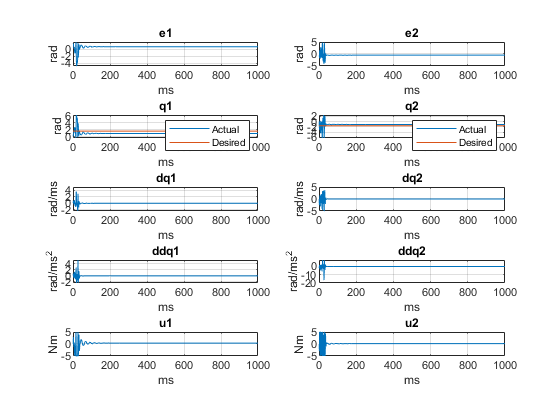

num_steps = floor(T / dt);
data_mat(1:12, num_steps) = 0.0;
for i = 1:dt:T
    %qd = [sin(i / 100); cos(i / 50)];
    % Update plot
    data_mat = data_store(data_mat, i, q, dq, ddq, err, u, qd);
    err = double(qd - q);
    derr = (err - err_prec) * idt;
    % Compute u
    u = controller_lqr(q, dq, ddq, ar, D, N, qd, false);
    %u = controller_pp_sm(q, dq, ddq, ar, D, N, qd, err, derr);
    %u = controller_pp(q, dq, ddq, ar, D, N, qd);
    %u = controller_d(q, dq, ddq, ar, D, N, kp, kd, err, err_prec);
    %u = controller_dext(q, dq, ddq, ar, D, N, kp, kd, err, err_prec);
    %u = controller_pd(q, dq, ddq, ar, D, N, kp, kd, err, err_prec);
    %u = controller_fbl(q, dq, ddq, ar, D, N, kp, kd, err, err_prec);
    
    % Clamp u 
    u(1) = max(min(uconstr(1, 2), u(1)), uconstr(1, 1));
    u(2) = max(min(uconstr(2, 2), u(2)), uconstr(2, 1));
    
    [q, dq, ddq] = step_2r_model(dt, q, dq, u, a, Dr, qconstr, dqconstr);
    err_prec = err;
end
labels = [["ms", "rad"]; ["ms", "rad"]; ["ms", "rad"]; ["ms", "rad"]; ["ms", "rad/ms"]; ["ms", "rad/ms"]; ["ms", "rad/ms^2"]; ["ms", "rad/ms^2"]; ["ms", "Nm"]; ["ms", "Nm"]];
titles = ["e1"; "e2"; "q1"; "q2"; "dq1"; "dq2"; "ddq1"; "ddq2"; "u1"; "u2"];
data_plot(data_mat, labels, 5, 2, titles);